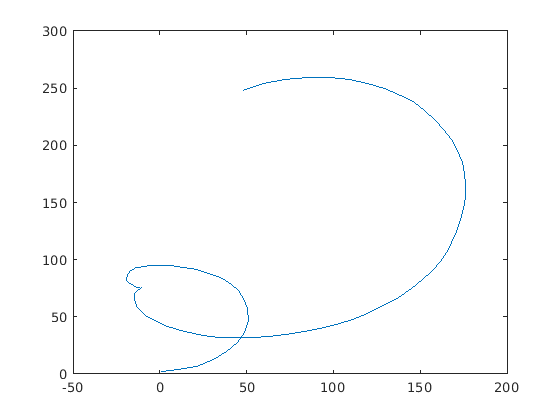

N= 100;
T = 1;

x_0 = [0 0 10 0 0];
P_0 = diag([10 10 2 pi/180 pi/360]);
f = @(x)coordinatedTurnMotion(x, T);
sigma_v = 1;
sigma_w = pi/180;
Q = diag([0 0 sigma_v 0 sigma_w]).^2;

X = genNonLinearStateSequence(x_0, P_0, f, Q, N);
true_x = X(1,:);
true_y = X(2,:);
figure(1)
plot(true_x, true_y)

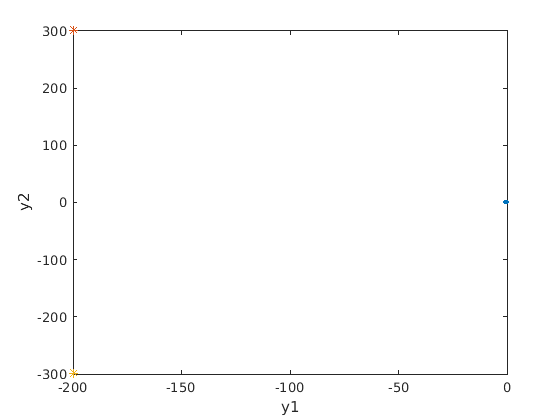

s1 = [-200, 300]';
s2 = [-200, -300]';

% case 1
sigma_r = pi/360;
R=diag([sigma_r sigma_r]).^2;
m = size(R,1);

measModel = @(X) dualBearingMeasurement(X, s1, s2);
Y = genNonLinearMeasurementSequence(X, measModel, R);

figure(1),clf
plot(Y(1,:),Y(2,:),'.')
hold on
plot(s1(1),s1(2),'*')
plot(s2(1),s2(2),'*')
xlabel('y1');ylabel('y2');